clear
clc

s1 = readmatrix("Setup1");
s2 = readmatrix("Setup2");

[DV_max,i_max] = max(abs(s1(:,2)-s2(:,2)));
DV_max = DV_max / s1(i_max,2) * 100

DV_max = 0.9797

[DV_min,i_min] = min(abs(s1(:,2)-s2(:,2)));
DV_min = DV_min / s1(i_min,2) * 100

DV_min = 0.2706

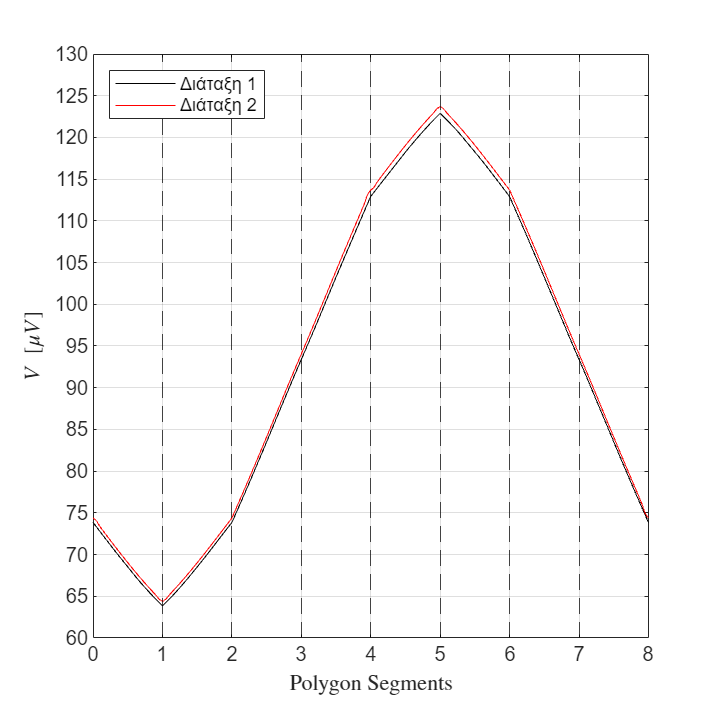


fg = figure("Position",[0,0,600,600]);
plot(s1(:,1),s1(:,2),'k')
hold on
plot(s2(:,1),s2(:,2),'r')
for i=1:7
    xline(i*s1(end,1)/8,'k--')
end
hold off
xlim([s1(1,1),s1(end,1)])
xticks(0:s1(end,1)/8:s1(end,1))
xticklabels(string(0:8))
yticks(60:5:130)
xlabel("Polygon Segments","Interpreter","latex")
ylabel("$V\ [\mu V]$","Interpreter","latex")
grid on

legend(["Διάταξη 1","Διάταξη 2"],"Location","northwest")

saveas(fg,"MAXWELL_Setup_Comparison.svg","svg");